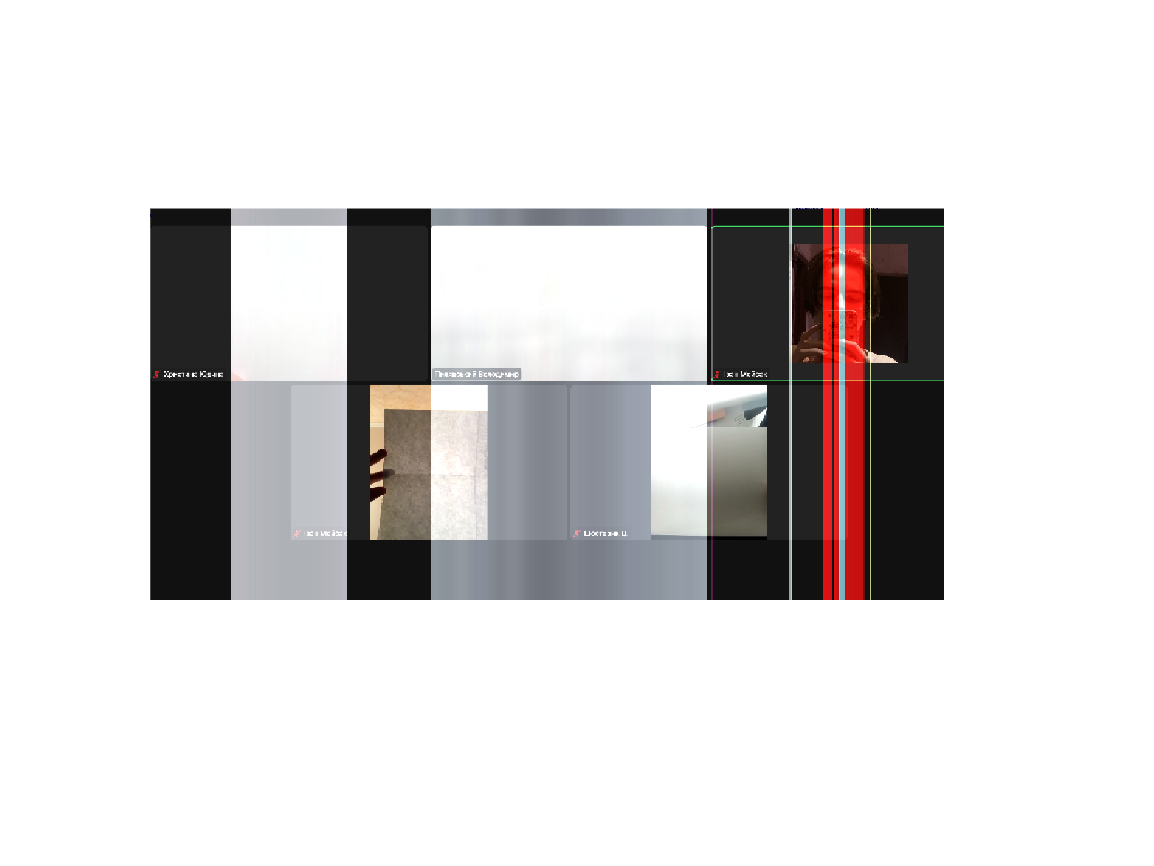


% Зчитування файлу зображення
image = imread("all.png"); 


% Обрання рядка зображення для дослідження
hold on
plot(image(330,:,1),'r');
plot(image(330,:,2),'g');
plot(image(330,:,3),'b');
% : - всі елементи в рядку, 1- червоний, 2 - зелений, 3- синій

% Визначення рівня сигналу

red = image(330,:,1);
green = image(330,:,2);
blue = image(330,:,3);


% Визначення корегуючих коефіцієнтів
% Обмеження оброблення зображення по горизонталі
Ered = 255; Egreen = 255; Eblue = 255;
if image(330,:,1)<2000
   Kred = 255-red;
   Kgreen = 255-green;
   Kblue = 255-blue;
else 
   Kred = 0;
   Kgreen = 0;
   Kblue = 0;
end
% Обмещення рівня сигналу корегуючих коефіціентів на рівні 205

for i=1:1:2664
    if Kred(i)<205; Kred(i)=Kred(i);else Kred(i)=0; end
    if Kgreen(i)<205; Kgreen(i)=Kgreen(i);else Kgreen(i)=0; end
    if Kblue(i)<205; Kblue(i)=Kblue(i);else Kblue(i)=0; end
end

% Корегування зображення

NEWimage(:,:,1) = image(:,:,1)+Kred;
NEWimage(:,:,2) = image(:,:,2)+Kgreen;
NEWimage(:,:,3) = image(:,:,3)+Kblue;

%Відтворення зображення
imshow(NEWimage)